# Material Addition in 2D

All material addition must be transient simulations. 

(As I understand) - A good summary [https://doi.org/10.1002/mdp2.56](https://doi.org/10.1002/mdp2.56)

Quiet Activation Strategy - The material properties are set to appropriate values only when the material is supposed to be active - for instance, the laser reaches that physical location. The "non-existing" material properties are typically very low/high. 

On/off Switch or Inactive element Activation- The entire boundary evolves requiring "re-solving" (even re-meshing?) for every "bunch of material addition"

General heat equation: $\rho c_p \frac{\partial T}{\partial t} - \nabla.(k\nabla T)= Q(x,y,t)$

clear;
close all;

k = 1; % thermal conductivity of copper, W/(m-K)
rho = 0.00844; % density of copper, kg/m^3
specificHeat = 410; % specific heat of copper, J/(kg-K)

Assume a movement of "line heat source" and the material "evolves with it"

Say 10 scans - i.e., 10 segments are added one by one to make a rectangle. 

Just a single meshing 

So, essentially (ignoring the temperature dependance of material properties)

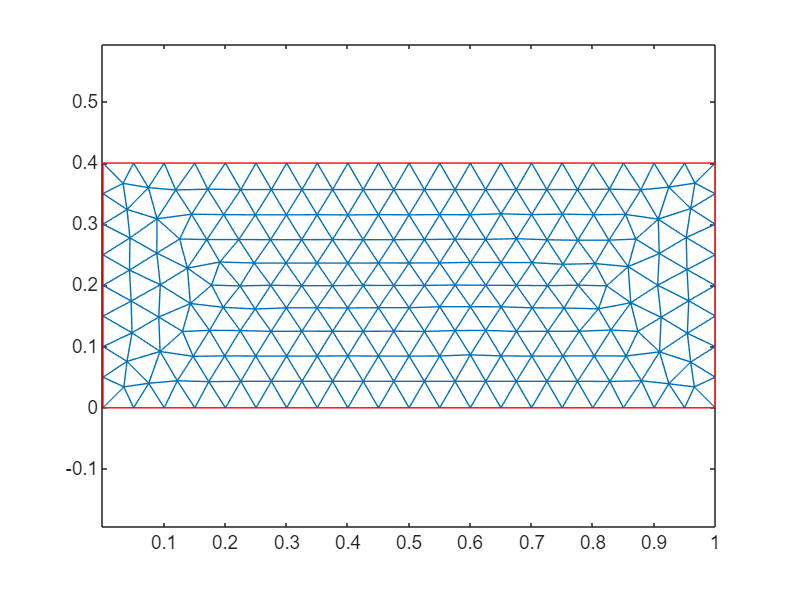

width = 1;
height = 0.4;
hmax = 0.05;

gdm = [3 4 0 width width 0 0 0 height height]'; %Describes a geometry
dl = decsg(gdm, 'S1', ('S1')');

numberOfPDE = 1;
model = createpde(numberOfPDE);

geometryFromEdges(model,dl);

msh = generateMesh(model,'Hmax',hmax,"GeometricOrder","linear");

figure
pdemesh(model)


$$\rho(x,y,t) c_p(x,y,t) \frac{\partial T}{\partial t} - \nabla.(k(x,y,t) \nabla T)= Q(x,y,t)$$


Functions 